**2. Considere o seguinte “jogo”: lançamento com os olhos vendados de n dardos, um de cada vez, para m alvos, garantindo-se que cada dardo atinge sempre um alvo (e apenas 1).**

**(a) **Estime por simulação a probabilidade de nenhum alvo ter sido atingido mais do que uma vez quando n = 20 dardos e m = 100 alvos.

experiencias_a = randi(100, 20, 1e6)

experiencias_a =     92    17    37    35     2    37    51    29    83     8     7    69    24    47    63    57    42    93    35    98    86    22    23    86    99    40    41    27    16     4     6    17    74    19    43    93    86    38    80    48    80   100    88    51    86    25    22    14    73     7
    81    41     6    81    26    82   100    34    45     3    65    11    34    58    51    68    80    73    34    81     1    89    29    16     9    26    14    98    12    23   100    70    89    18    84    46    28    55     1    24    66    39    91    36    67    54    22    86    94    89
    99    63    52    21    80   100    94    66    99    28    54    44    35    19    24    29    80    49    88    21    73    60    92    37    61    46    37    50    91    99    92    49    23    30    83    77    82    42    27     6     6     6   100    66    72    87    60    94    40    42
    43    67    80    61   100    39    22    90    93    57    98    67    21  

CasosFavoraveis_a = 0;
for k=1:1e6
    if length(unique(experiencias_a(:,k))) == 20
        CasosFavoraveis_a = CasosFavoraveis_a + 1;
    end
end

probSimulacao_a = CasosFavoraveis_a/1e6

probSimulacao_a = 0.1298

**(b)** Estime por simulação a probabilidade de pelo menos 1 alvo ter sido atingido 2 ou mais vezes quando n = 20 dardos e m = 100 alvos.

experiencias_b = randi(100, 20, 1e6)

experiencias_b =     32    95     1    48    21    26    22    66    54    22    80    41    28    46     7    76    34    32    40    80     1    35    75     7     1    82    10   100    62    76    68    61    77    88    35    10    23    27    13    17    77    24     1    92    35    15    58    71    93    73
    85    78    28    14    92    15    50    51    95    35     5    47    99    27    89    87    13    83    28    71    31    12    37    26    10    54    87    44    35    62    57    92    63   100    84    26    60    65    54    50     8    87     7    81    46    52     7    78    99    88
    76    44    36    87    75    67    64     8    62    63    58    14    21    78    52    36    80    41     2    95    21    95    48    78    42    71    54    29    77    69    18    68    22    23    34    10     3    91     9    91    97    18    37    21    38    82    50    36     3    22
    22    45    63     5    13    80    77    71    52    18    86    99    87  

CasosFavoraveis_b = 0

CasosFavoraveis_b = 0

for k=1:1e6
    if length(unique(experiencias_b(:,k))) < 20
        CasosFavoraveis_b = CasosFavoraveis_b + 1;
    end
end

probSimulacao_b = CasosFavoraveis_b/1e6

probSimulacao_b = 0.8698

**(c)** Considere os valores de m = 1000 e m = 100000 alvos. Para cada um destes valores, faça as simulações necessárias para desenhar um gráfico (usando a função plot do Matlab) da probabilidade da alinea (b) em função do número de dardos n. Considere n de 10 a 100 com incrementos de 10. Os 2 gráficos devem ser sub-gráficos de uma mesma figura (use a instrução subplot do Matlab). Compare os resultados dos 2 casos e retire conclusões.

n = 10:10:100

n =     10    20    30    40    50    60    70    80    90   100


m1 = 1000

m1 = 1000

m2 = 100000

m2 = 100000

y1 = zeros(size(n))

y1 =      0     0     0     0     0     0     0     0     0     0


y2 = zeros(size(n))

y2 =      0     0     0     0     0     0     0     0     0     0


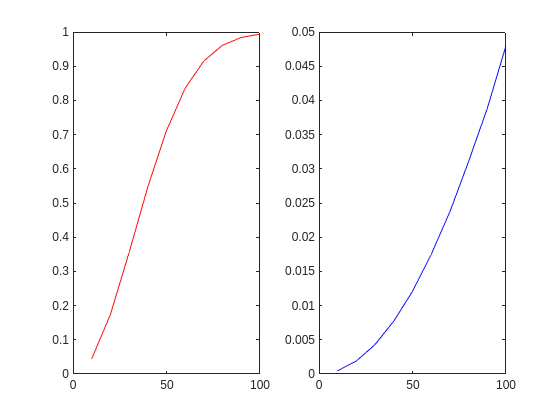


for i = 1:length(n)
    y1(i) = calcularProbabilidade(n(i), m1); 
    y2(i) = calcularProbabilidade(n(i), m2); 
end

subplot(1, 2, 1)
plot(n, y1, 'r')

subplot(1, 2, 2)
plot(n, y2, 'b')

**(d)** Considere o valor de n = 100 dardos. Faça as simulações necessárias para desenhar um gráfico da probabilidade da alínea (b) em função dos valores de m = 200, 500, 1000, 2000, 5000, 10000, 20000, 50000 e 100000 alvos. O que conclui dos resultados obtidos?

n = 100

n = 100

m = [200, 500, 1000, 2000, 5000, 10000, 20000, 50000, 100000 ]

m =          200         500        1000        2000        5000       10000       20000       50000      100000


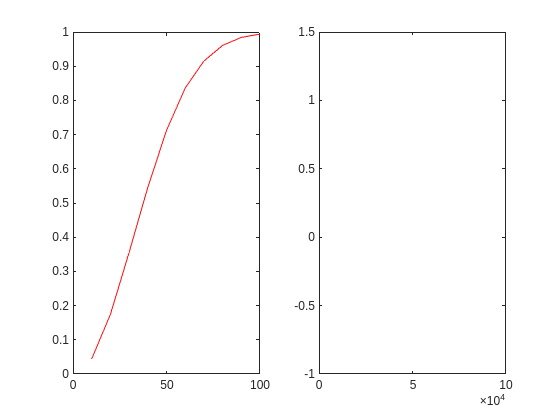


for i = 1:length(m)
    y = calcularProbabilidade(n, m(i));
end

plot(m, y, 'r')